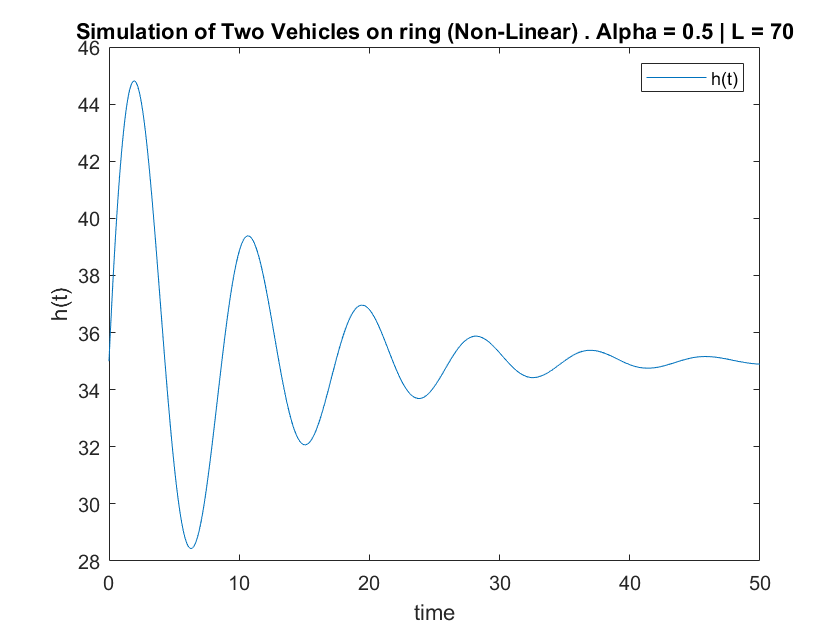

%HW3_Q3 Two Vehicle on the ring. (Without Linearizing)
clear all; close all;

%Parameters
tau = 0.8;
tstart = 0;
tdelta = 0.1;
tend = 50;
tspan = tstart:tdelta:tend;
vmax = 30;
hst = 5;
hgo = 45;


%Parameters selection after studying the stability chart.
alpha = 0.5;
L = 70;
kappa = vmax*(2*hgo - L)/(hgo - hst)^2;

%Initial Condition. Equivalent to y0 of ode45.
ic = @(t)[35 20 30]; 

%For plotting History
hist = tstart-tau:tdelta:tstart;
ic_1 = @(t)1;

%DDE setup
sol = dde23(@(t,y,ytau)ddefunc(t,y,ytau,alpha,kappa,vmax,L,hst,hgo),tau,ic,tspan);
y = deval(sol,tspan);

%Plotting. (For linearized system, everything is in terms of perturbations)
figure(1);box on;
plot(tspan,y(1,:));
xlabel("time");
ylabel('h(t)');
title("Simulation of Two Vehicles on ring (Non-Linear) . Alpha = "+alpha+" | L = "+L);
legend('h(t)');

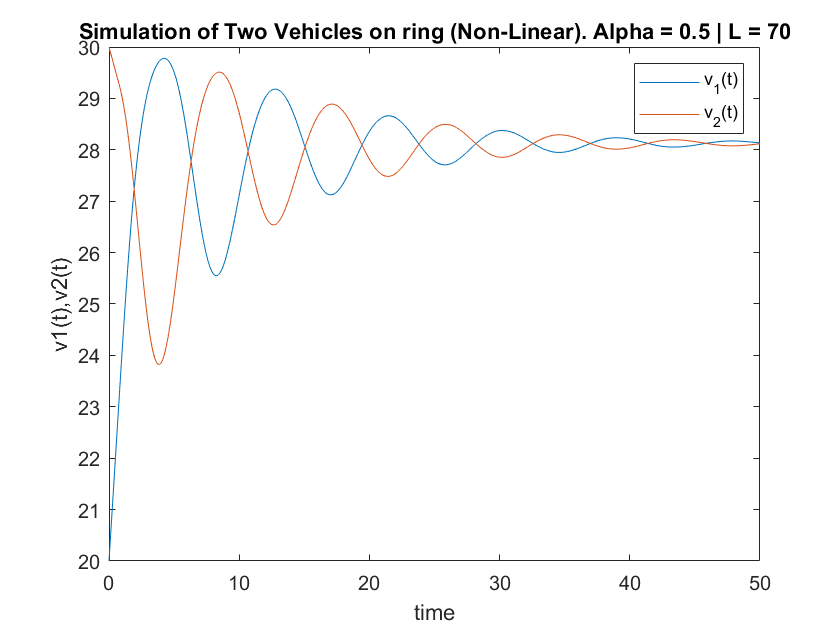



figure(2);box on; hold on;
plot(tspan,y(2,:));
plot(tspan,y(3,:));
xlabel("time");
ylabel('v1(t),v2(t)');
title("Simulation of Two Vehicles on ring (Non-Linear). Alpha = "+alpha+" | L = "+L);
legend('v_1(t)' , 'v_2(t)');

function dydt = ddefunc(t,y,ytau,alpha,kappa,vmax,L,hst,hgo)
    h = y(1);
    
    dydt(1) = y(3) - y(2);
    dydt(2) = alpha*(0 + ((hst<h)&(h<hgo))*vmax*(2*hgo - hst - ytau(1))*(ytau(1)-hst)/(hgo-hst)^2 + (h>=hgo)*vmax) - alpha*ytau(2);
    dydt(3) = alpha*(0 + ((hst<h)&(h<hgo))*vmax*(2*hgo - hst - (L-ytau(1)))*((L-ytau(1))-hst)/(hgo-hst)^2 + (h>=hgo)*vmax) - alpha*ytau(3);
    
    dydt = dydt';
end

